## AAE 440 PS7 p3

clear all; close all; clc;

fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW7';
set(groot, 'defaulttextinterpreter',"latex");
set(groot, 'defaultAxesTickLabelInterpreter',"latex");
set(groot, 'defaultLegendInterpreter',"latex");

% Draw Arrow Function
drawArrow = @(x,y,varargin) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0, varargin{:});

% Setting given properties 
I_body = [4000 0 0; 0 9000 0; 0 0 9000];
k = 1;
d_1 = k*I_body(1,1)^(-0.5);
d_2 = k*I_body(2,2)^(-0.5);
d_3 = k*I_body(3,3)^(-0.5);
theta = 0:0.01:2*pi;

### <a>

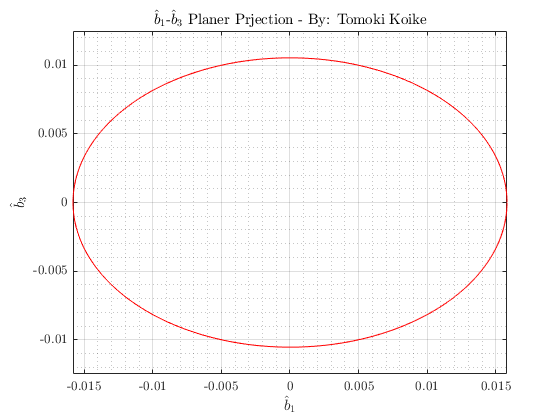

% Plotting
% b1-b3
fig1 = figure("Renderer","painters");
    plot(d_1*cos(theta), d_3*sin(theta), 'r')
    title('$\hat{b}_1$-$\hat{b}_3$ Planer Prjection - By: Tomoki Koike')
    xlabel('$\hat{b}_1$')
    ylabel('$\hat{b}_3$')
    grid on; grid minor; box on; axis equal;
saveas(fig1, fullfile(fdir,'b1_b3_ellipse3.png'));

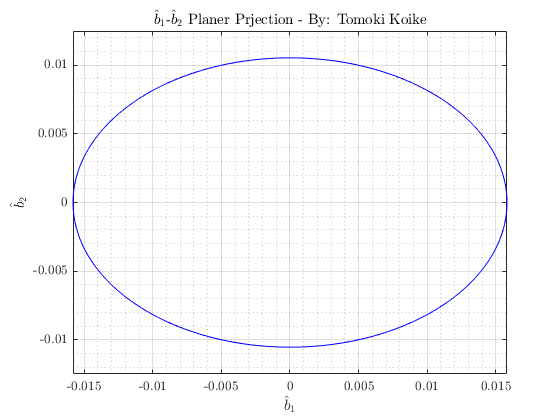


% b1-b2
fig2 = figure("Renderer","painters");
    plot(d_1*cos(theta), d_2*sin(theta), 'b')
    title('$\hat{b}_1$-$\hat{b}_2$ Planer Prjection - By: Tomoki Koike')
    xlabel('$\hat{b}_1$')
    ylabel('$\hat{b}_2$')
    grid on; grid minor; box on; axis equal;
saveas(fig2, fullfile(fdir,'b1_b2_ellipse3.png'));

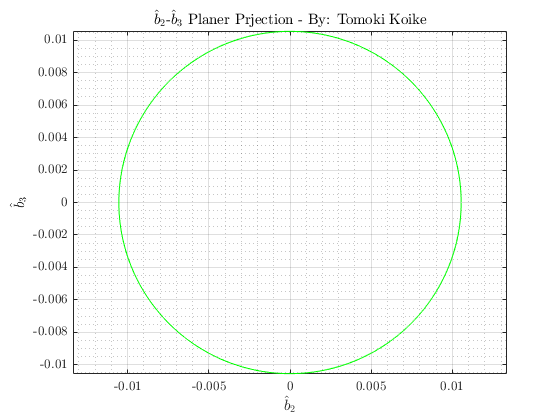


% b2-b3
fig3 = figure("Renderer","painters");
    plot(d_2*cos(theta), d_3*sin(theta), 'g')
    title('$\hat{b}_2$-$\hat{b}_3$ Planer Prjection - By: Tomoki Koike')
    xlabel('$\hat{b}_2$')
    ylabel('$\hat{b}_3$')
    grid on; grid minor; box on; axis equal;
saveas(fig3, fullfile(fdir,'b2_b3_ellipse3.png'));

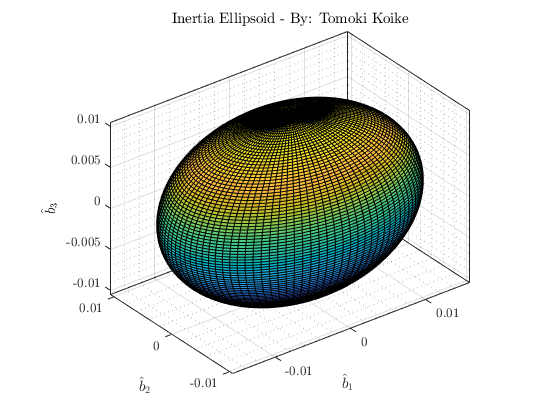


% Ellipsoid
fig4 = figure("Renderer","painters");
    ellipsoid(0,0,0,d_1,d_2,d_3,100)
    title('Inertia Ellipsoid - By: Tomoki Koike')
    xlabel('$\hat{b}_1$')
    ylabel('$\hat{b}_2$')
    zlabel('$\hat{b}_3$')
    grid on; grid minor; box on; axis equal;
saveas(fig4, fullfile(fdir,'ellipsoid3.png'));

### <b>

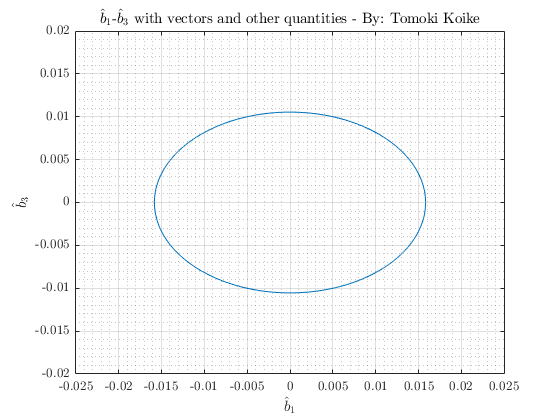

% Defining properties
T = 0;  % Torque  [N-m]
I_cm = [4000 0 0; 0 9000 0; 0 0 9000];   % Inertia Dyadic  [kg-m2]
I = 9000;
J = 4000;

% Defining the angular velocity
w_mag = 3; % Magnitude of angular velocity 
ang = deg2rad(60); % [rad]
w_NB = [w_mag*cos(ang) 0 -w_mag*sin(ang)];

% Angular Momentum
H_NB = I_cm*w_NB';


% Replotting b1-b3 and adding vectors and quantities
fig5 = figure("Renderer","painters");
    plot(d_1*cos(theta), d_3*sin(theta))
    title('$\hat{b}_1$-$\hat{b}_3$ with vectors and other quantities - By: Tomoki Koike')
    xlabel('$\hat{b}_1$')
    ylabel('$\hat{b}_3$')
    hold on; grid on; grid minor; box on; axis equal;
    xlim([-0.025, 0.025]); ylim([-0.020, 0.020]);
saveas(fig5, fullfile(fdir,'b1_b3_ellipse_new.png'));

### <c>

% angles @ t = 1
p = norm(H_NB)/I; % precession rate
s = (I-J)/I*w_NB(1); % spin rate
phi = acos(J/norm(H_NB)*w_NB(1)); % nutation angle = constant

% t = 0.4, 3.0, 6.0
t = [0.4 3.0 6.0];
p_rad = p.*t;
s_rad = s.*t;
phi_deg = rad2deg(phi)

phi_deg = 75.6084

p_deg = rad2deg(p_rad)

p_deg =    61.4726  461.0442  922.0883


s_deg = rad2deg(s_rad)

s_deg =    19.0986  143.2394  286.4789


## <d>

% Euler Parameters 
e_04_c = EulerPara_from_OrientAngs(0.4,p,s,phi);
e_30_c = EulerPara_from_OrientAngs(3.0,p,s,phi);
e_60_c = EulerPara_from_OrientAngs(6.0,p,s,phi);

% t = 0.4s
t = 0.4;
e_04_c = [e_04_c(1) e_04_c(2) e_04_c(3)];
C_CB_04 = [1 0 0; 0 cos(s*t) -sin(s*t); 0 sin(s*t) cos(s*t)];
e_04_b = e_04_c*C_CB_04

% t = 3.0s
t = 3.0;
e_30_c = [e_30_c(1) e_30_c(2) e_30_c(3)];
C_CB_30 = [1 0 0; 0 cos(s*t) -sin(s*t); 0 sin(s*t) cos(s*t)];
e_30_b = e_30_c*C_CB_30

% t = 6.0s
t = 6.0;
e_60_c = [e_60_c(1) e_60_c(2) e_60_c(3)];
C_CB_60 = [1 0 0; 0 cos(s*t) -sin(s*t); 0 sin(s*t) cos(s*t)];
e_60_b = e_60_c*C_CB_60

## <e>

% maximum of zeta
zeta = 2*phi;
 
% time corresponding to the maximum zeta
t_maxzeta = pi/p;

% Euler parameters corresponding
e_maxzeta = EulerPara_from_OrientAngs(t_maxzeta,p,s,phi)

e_maxzeta =     0.2195   -0.4542   -0.8555   -0.1165


## <f>

% t = 6.0 s
C = DCM_Body(1, 2, 1, p_rad(3), phi, s_rad(3));
theta2 = asin(-C(2,3))

theta2 = 1.0393

theta1 = -acos(C(2,2)/cos(theta2))

theta1 = -2.3398

theta1 = -pi-asin(C(2,1)/cos(theta2))

theta1 = -2.3398

theta3 = pi-asin(C(1,3)/cos(theta2))

theta3 = 2.5687

theta3 = acos(C(3,3)/cos(theta2))

theta3 = 2.5687

 
theta1 = rad2deg(theta1)

theta1 = -134.0593

theta2 = rad2deg(theta2)

theta2 = 59.5456

theta3 = rad2deg(theta3)

theta3 = 147.1739